# Euler Rats

**Model:**   Implement a local rate function for the rate population model.

function res = rate_func(t, rats)
    %RATE_FUNC returns the growth rate at time (t) for population (rats)
    a = 0.002;
    omega = 2*pi / 365;
    res = a * rats * (1 - cos(omega * t));
end

**ODE45 Solution:** An implementation of the `ode45` solution, which you can again use the code from the textbook as a model.

Initial condition - 1000 rats

rats_init = 1000; 

Time span - 1 year = 365 days

t_span = [0, 365];

Optional: Turn on the statistics option to get more information about how the solver works.

opts = odeset(Stats="on");

Call the solver and pass the function handle.

[tt, rats] = ode45(@rate_func, t_span, rats_init, opts);

10 successful steps
0 failed attempts
61 function evaluations


**Euler Solution:** An implementation of he `euler` solution using your Euler solver for the same scenario.

[tte, rats_euler] = euler(@rate_func, t_span, rats_init);

**Comparison: **Plotting to visually compare the two solutions (`ode45`  and `euler`) on one graph.

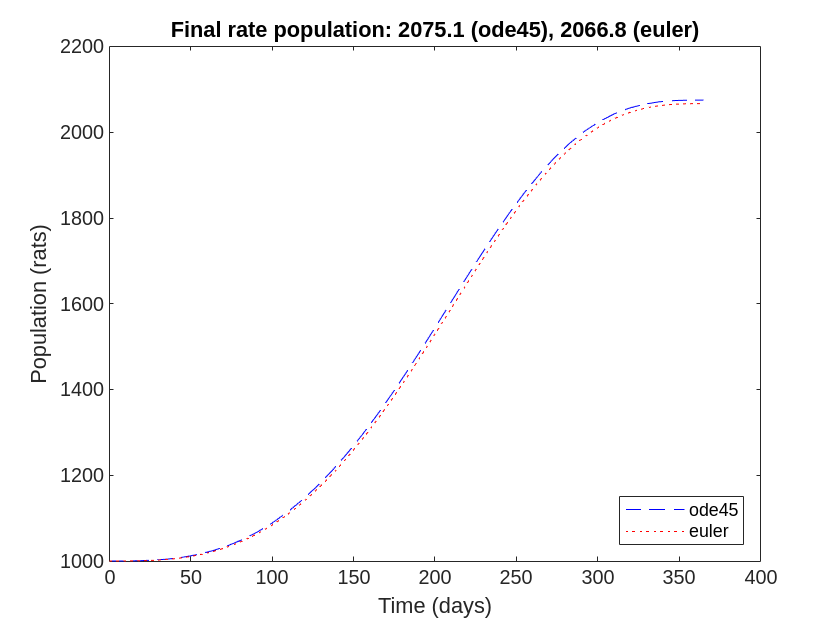

figure(1);
clf()
plot(tt, rats, 'b--')
hold on;
plot(tte, rats_euler, "r:")
xlabel('Time (days)')
ylabel('Population (rats)')

legend('ode45','euler','location','southeast')
title(sprintf("Final rate population: %.1f (ode45), %.1f (euler)", ...
    rats(end), rats_euler(end)));